clearvars;

## Image Source Method

We excecute the ims method now for a grid of measurement points.

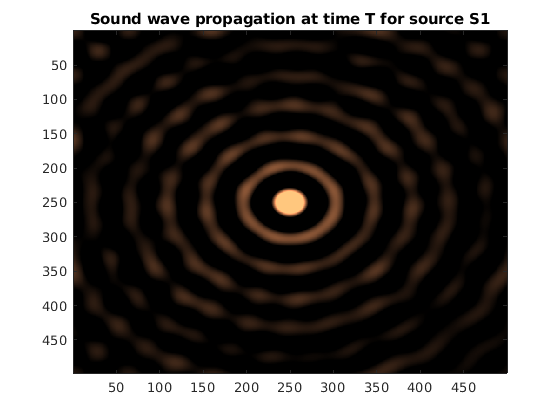

beta = 1; n = 500;
L = [n,n,n]; spacing = 0.01;
f = 800; c = 343; omega = 2*pi*f; phase = 0;
S1 = [n/2,n/2,n/2];
alpha = [0.5,0.9,0.5,0.9,0.5,0.5];
order = 1;
p1 = zeros(n-1,n-1);

for x=1:n-1
    for y=1:n-1
        p1(x,y) = ISM(S1,[x,y,n/2],L,phase,omega,c,alpha,order,spacing);
    end
end
figure;
colorScale = mean(mean(imag(p1(abs(p1) ~= inf))));
image(imag(p1)/colorScale); colormap copper;
title("Sound wave propagation at time T for source S1");

Lets add a second source, just to see what the output is

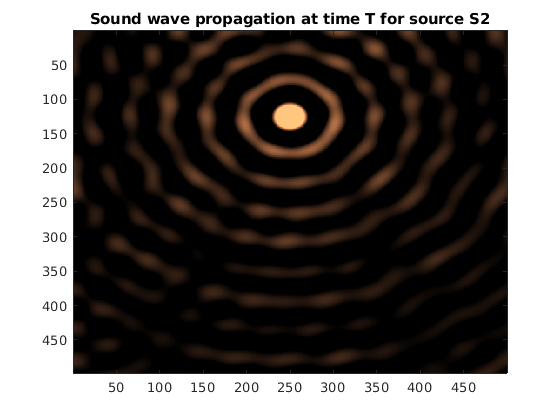

S2 = [round(n/4),n/2,n/2];
p2 = zeros(n-1,n-1);

for x=1:n-1
    for y=1:n-1
        p2(x,y) = ISM(S2,[x,y,n/2],L,phase,omega,c,alpha,order,spacing);
    end
end
figure;
colorScale = mean(mean(imag(p2(abs(p2) ~= inf))));
image(imag(p2)/colorScale); colormap copper;
title("Sound wave propagation at time T for source S2");

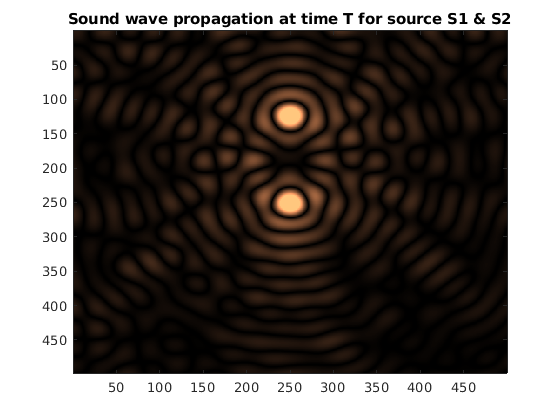

p = p1+p2;
figure;
colorScale = mean(mean(imag(p(abs(p) ~= inf))));
image(abs(imag(p))/colorScale); colormap copper;
title("Sound wave propagation at time T for source S1 & S2");